# Risolve Testing

## **Testing di robustezza**

### **Testing sul numero di input**

A=rand(100,100);
x=ones(100,1);
b=A*x;
y=risolve(A,b)

Error using risolve (line 6)
Inserire i 3 parametri di input: Matrice, vettore e struttura.

### **Testing sulla matrice**

Testo se non è una matrice

A=rand(100,100,100);
x=ones(100,1);
b=[1:100]';
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 10)
Il primo input deve essere una matrice.

Testo se non è quadrata

A=rand(50,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 14)
La matrice deve essere quadrata.

Testo se è di dimensione minore di 2

A=1;
x=2;
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 14)
La matrice deve essere quadrata di dimensione almeno 2x2.

Testo se è sparsa o vuota

A=sparse(rand(100,100));
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 12)
La matrice non deve essere sparsa o vuota.

A=[];
x=ones(100,1);
b=x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 12)
La matrice non deve essere sparsa o vuota.

Testo se non contiene numeri reali

A=rand(100,100);
A(50,92)=Inf;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 16)
Gli elementi della matrice devono essere numeri reali double finiti.

A=rand(100,100);
A(14,10)=NaN;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 16)
Gli elementi della matrice devono essere numeri reali double finiti.

**Testing sul vettore**

Testo se non è un vettore

A=rand(100,100);
x=ones(100,1);
b=4;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 21)
Errore, b deve essere un vettore colonna.

Testo se non è un vettore colonna

A=rand(100,100);
x=ones(100,1);
b=[2 3];
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 21)
Errore, b deve essere un vettore colonna.

Testo se il vettore e la matrice hanno dimensioni diverse

A=rand(100,100);
x=ones(100,1);
b=[A*x; 10];
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 23)
Il vettore b e la matrice A hanno dimensioni diverse.

Testo se non contiene reali finiti double

A=rand(100,100);
x=ones(100,1);
b=A*x;
b(30)=Inf;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 25)
Errore, b deve contenere reali finiti double.

**Testing sulla struttura**

Testo se non è una struttura

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt=29;
y=risolve(A,b,opt)

Error using risolve (line 30)
Il terzo parametro deve essere una struttura

Testo se non ha tre campi

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
opt.quarto=true;
y=risolve(A,b,opt)

Error using risolve (line 32)
La struttura deve avere tre campi.

Testo se i campi non hanno i nomi specificati

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.campo=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 34)
I tre campi della struttura opt devono chiamarsi full, sup e inf.

Testo se i campi della struttura non sono logici

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=5;
y=risolve(A,b,opt)

Error using risolve (line 36)
I tre campi della struttura devono essere logici (true/false).

Testo se il numero di campi true è diverso da uno

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve (line 38)
Uno e un solo campo della struttura deve essere true.

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve (line 38)
Uno e un solo campo della struttura deve essere true.

**Testing sulla singolarità delle matrici**

Testo se la matrice triangolare superiore è singolare

A=rand(100,100);
A=triu(A)+diag(ones(100,1));
A(25,25)=0;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve (line 42)
La matrice triangolare è singolare.

Testo se la matrice triangolare inferiore è singolare

A=rand(100,100);
A=tril(A)+diag(ones(100,1));
A(50,50)=0;
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve (line 42)
La matrice triangolare è singolare.

Testo se nella funzione Gauss il sistema è singolare.

A=rand(100,100);
A(50,:)=0;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve>gauss (line 98)
Gauss:Il sistema è singolare.

Error in risolve (line 48)
        x=gauss(A,b);

## **Testing di Funzionamento**

Testing funzionamento back substitution

A=rand(100,100);
A=triu(A)+diag(ones(100,1));
cond=cond(A)

cond =      8.312082505603721e+02


x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

y =    0.999999999999963   1.000000000000004   0.999999999999984   1.000000000000000   1.000000000000012   0.999999999999977   1.000000000000014   1.000000000000024   1.000000000000017   0.999999999999988   1.000000000000011   0.999999999999977   0.999999999999981   1.000000000000000   1.000000000000004   1.000000000000004   1.000000000000013   0.999999999999991   0.999999999999990   1.000000000000004   1.000000000000004   0.999999999999998   0.999999999999981   1.000000000000029   1.000000000000028   1.000000000000011   1.000000000000004   0.999999999999967   0.999999999999983   1.000000000000010   0.999999999999994   1.000000000000007   1.000000000000013   0.999999999999987   1.000000000000002   1.000000000000007   1.000000000000012   0.999999999999986   1.000000000000000   1.000000000000000   0.999999999999997   0.999999999999996   0.999999999999991   0.999999999999997   1.000000000000007   1.000000000000003   1.000000000000006   1.000000000000006   1.000000000000001   0.99999999999

Testing funzionamento forward substitution

A=rand(100,100);
A=tril(A)+diag(ones(100,1));
cond=cond(A)

cond =      6.726834166225296e+02


x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

y =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000001   0.999999999999999   1.000000000000001   1.000000000000001   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000001   0.999999999999999   1.000000000000000   1.000000000000000   1.000000000000002   0.999999999999997   1.000000000000001   1.000000000000000   1.000000000000002   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000002   0.999999999999998   1.000000000000001   1.000000000000002   1.000000000000001   0.999999999999998   1.000000000000004   1.000000000000002   0.999999999999994   0.999999999999994   0.999999999999997   1.000000000000008   1.000000000000000   0.999999999999999   0.999999999999994   1.000000000000004   1.000000000000001   1.000000000000001   1.000000000000005   0.999999999999988   0.99999999999

Testing funzionamento gauss pivoting parziale virtuale

A=rand(100,100);
x=ones(100,1);
cond=cond(A)

cond =      8.282298357374498e+02


b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

y =    1.000000000000107   1.000000000000012   0.999999999999989   1.000000000000089   1.000000000000010   1.000000000000016   0.999999999999993   0.999999999999992   0.999999999999973   0.999999999999944   0.999999999999990   1.000000000000001   0.999999999999999   0.999999999999986   0.999999999999936   0.999999999999937   1.000000000000036   0.999999999999985   1.000000000000046   1.000000000000048   0.999999999999975   0.999999999999974   1.000000000000025   1.000000000000036   0.999999999999956   0.999999999999998   1.000000000000026   1.000000000000000   1.000000000000005   1.000000000000000   0.999999999999905   0.999999999999936   0.999999999999996   0.999999999999994   1.000000000000006   0.999999999999976   0.999999999999985   0.999999999999986   0.999999999999968   1.000000000000007   1.000000000000007   0.999999999999960   1.000000000000080   1.000000000000047   1.000000000000060   0.999999999999988   0.999999999999990   0.999999999999951   0.999999999999977   1.00000000000

Testing se opt non è conforme con la matrice

A=rand(100,100);%matrice triu
A=triu(A)+diag(ones(100,1));
cond=cond(A)

cond =      6.739672652784668e+02


x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

y =   28.601785293648284  35.529907518657375  45.303445523737722  26.331776017292132  29.111743990657164  24.511961675452770  40.647771924673307  28.585243079449420  23.628223319562252  46.108035226408553  25.458034151430173  30.570724850638474  22.171920884664775  37.188808717285326  27.958126756414782  26.563597979019683  35.165553222517666  28.869973567733727  27.292565655234590  36.676800405682805  25.246407150179962  21.260212475914187  34.757645573809612  40.868024247371906  32.171925163595041  38.738863701202547  29.479540654177651  21.996176792922537  17.557834027819130  22.507691392820892  27.717990761276880  18.742732222940699  32.190799899719181  25.771660407331964  22.822912747884899  19.819065967386173  21.361040193575651  21.142807932207461  16.898398179921781  17.647143863187800  19.606878574809578  19.734557804666498  16.707139736864843  15.302959415388107  14.521138557661462  26.587090373050266  24.695927238365002  20.192268614517772  25.260402416619343  17.63737613333

A=rand(100,100);%matrice tril
A=tril(A)+diag(ones(100,1));
cond=cond(A)

cond =      5.744773654987055e+02


x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

y =    1.000000000000000   1.523465874811733   1.453393312250966   1.729466844777637   3.375475720503844   4.064734791998304   3.064162087209488   3.065557769786472   3.563647028092937   3.645030312847638   3.913257814952376   4.183534965600678   3.622921695743352   5.080624110167245   5.341702309691129   5.272516512652751   4.115902574628954   6.881506030349239   6.257821946330359   8.284550323037672   7.093653796949837   8.072167001160491   8.699625840840497  11.362970552983056   9.418751815307910  12.227737580932473   8.337705925649226  11.114065573509857  10.230906873372138  10.409475378218458  11.426355467886690   9.616086925127881  12.762266152632982  10.276243384436402  16.557371053811174   9.902423373495362  10.116115455329943  12.340912364789821  15.924858178660745  18.405647398384751  11.490280860920320  12.305866910420614  11.024079925041407  15.327172892929756  13.827402348270569  14.490379927662136  23.657403875927653  16.036547528993971  15.972464295092211  15.37547843522

A=rand(100,100);%matrice triu
cond=cond(A)

cond =      1.009206009977068e+03


x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

y = 	1.0e+24 *

   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000001   0.000000000000000   0.000000000000002  -0.000000000000006  -0.000000000000002   0.000000000000004   0.000000000000003  -0.000000000000001  -0.000000000000000   0.000000000000020  -0.000000000000520   0.000000000000267   0.000000000002355  -0.000000000000637  -0.000000000002958   0.000000000003445  -0.000000000008041  -0.000000000004154   0.000000000009295   0.000000000009860  -0.000000000008819   0.000000000028891  -0.000000000028712   0.000000000014701  -0.000000000010318  -0.000000000010338  -0.000000000044060   0.000000000040807   0.000000000023758  -0.000000000133386   0.000000000154344  -0.000000001240915   0

A=rand(100,100);%matrice triu
A=triu(A)+diag(ones(100,1));
cond=cond(A)

cond =      6.299619935479590e+02


x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

y =    0.999999999999952   0.999999999999975   1.000000000000006   0.999999999999996   0.999999999999970   0.999999999999948   0.999999999999989   1.000000000000013   1.000000000000032   0.999999999999993   1.000000000000029   1.000000000000024   1.000000000000026   0.999999999999979   1.000000000000036   0.999999999999984   0.999999999999957   1.000000000000002   0.999999999999971   1.000000000000050   0.999999999999992   1.000000000000014   0.999999999999984   1.000000000000007   0.999999999999963   0.999999999999984   1.000000000000008   1.000000000000054   0.999999999999979   0.999999999999984   1.000000000000018   0.999999999999999   1.000000000000010   0.999999999999987   0.999999999999996   0.999999999999997   1.000000000000013   0.999999999999993   0.999999999999999   0.999999999999997   1.000000000000021   0.999999999999991   1.000000000000004   1.000000000000002   0.999999999999992   0.999999999999989   1.000000000000003   0.999999999999997   1.000000000000004   1.00000000000

## Verifica teorema di Wilkinson

Verifica per gauss pivoting parziale virtuale

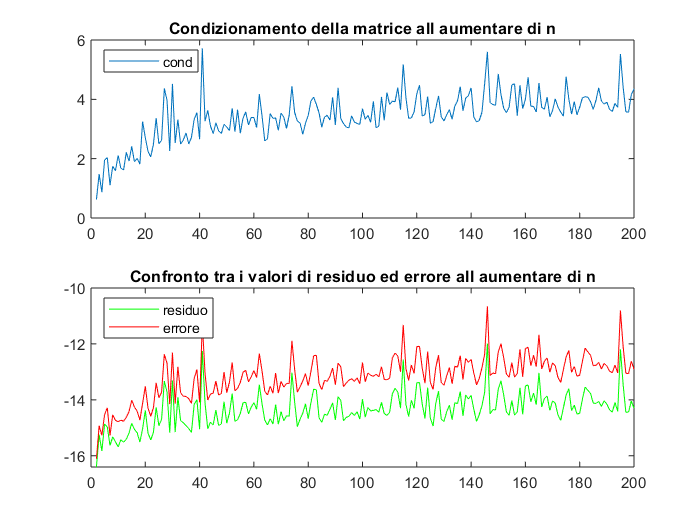

opt.inf=false;
opt.sup=false;
opt.full=true;
for n=2:200
    A=rand(n,n);
    x=2*ones(n,1);
    b=A*x;
    c(n)=cond(A);
    y=risolve(A,b,opt);
    re(n)=norm(A*y'-b)/(norm(A)*norm(y));
    er(n)=norm(x-y')/norm(x);
end
close all;
x=1:200;
subplot(2,1,1)
plot(x,log10(c))
title('Condizionamento della matrice all aumentare di n');
legend('cond','Location','northwest');
subplot(2,1,2)
plot(x,log10(re),'g')
hold on;
plot(x,log10(er),'r')
title('Confronto tra i valori di residuo ed errore all aumentare di n');
legend('residuo','errore','Location','northwest');

Verifica per una matrice malcondizionata

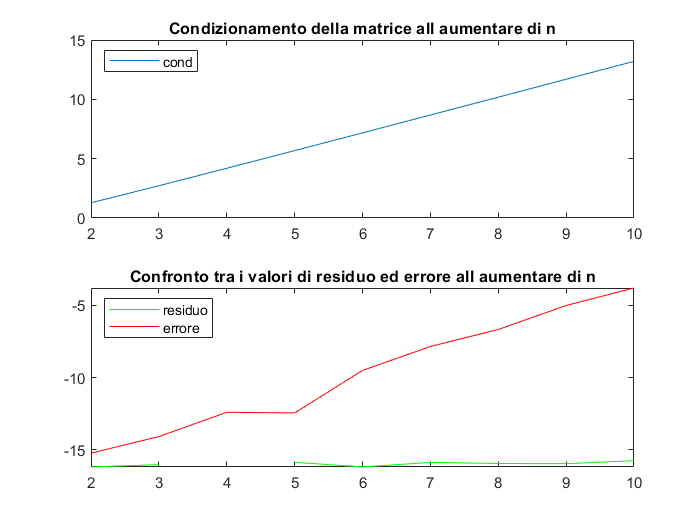

opt.inf=false;
opt.sup=false;
opt.full=true;
for n=2:10
    H=hilb(n);
    x=2*ones(n,1);
    b=H*x;
    c(n)=cond(H);
    y=risolve(H,b,opt);
    re(n)=norm(H*y'-b)/(norm(H)*norm(y));
    er(n)=norm(x-y')/norm(x);
end
close all;
x=1:10;
subplot(2,1,1)
plot(x,log10(c))
title('Condizionamento della matrice all aumentare di n');
legend('cond','Location','northwest');
subplot(2,1,2)
plot(x,log10(re),'g')
hold on;
plot(x,log10(er),'r')
title('Confronto tra i valori di residuo ed errore all aumentare di n');
legend('residuo','errore','Location','northwest');

Si nota che l'indice di condizionamento della matrice di hilbert è molto più grande rispetto agli altri casi anche se la dimensione della metrice è inferiore, quindi l'errore è da subito molto elevato.

## **Testing di Accuratezza**

Calcolo l'errore della back substitution

A=rand(100,100);
A=triu(A)+diag(ones(100,1));
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

y =    0.999999999999978   0.999999999999994   1.000000000000024   1.000000000000027   1.000000000000022   0.999999999999973   0.999999999999985   1.000000000000041   1.000000000000000   1.000000000000007   0.999999999999991   0.999999999999996   1.000000000000010   0.999999999999995   0.999999999999987   1.000000000000002   1.000000000000010   0.999999999999987   0.999999999999989   1.000000000000017   1.000000000000000   1.000000000000003   1.000000000000002   1.000000000000006   1.000000000000008   0.999999999999997   0.999999999999995   0.999999999999975   1.000000000000007   1.000000000000009   0.999999999999996   1.000000000000011   0.999999999999997   1.000000000000009   0.999999999999990   0.999999999999989   1.000000000000011   1.000000000000001   0.999999999999995   0.999999999999996   0.999999999999999   1.000000000000003   0.999999999999997   1.000000000000002   0.999999999999990   1.000000000000006   0.999999999999998   1.000000000000006   1.000000000000002   1.00000000000

cond=cond(A)

cond =      6.147176731527594e+02


err=norm(x-y')/norm(x)

err =      8.963894223692580e-15


Calcolo l'errore della forward substitution

A=rand(100,100);
A=tril(A)+diag(ones(100,1));
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

y =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000001   1.000000000000001   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000001   1.000000000000000   0.999999999999999   0.999999999999998   1.000000000000002   1.000000000000000   0.999999999999998   0.999999999999999   1.000000000000006   1.000000000000004   0.999999999999997   1.000000000000002   1.000000000000002   0.999999999999996   0.999999999999995   1.000000000000001   1.000000000000000   1.000000000000000   1.000000000000009   0.999999999999994   0.999999999999998   1.000000000000002   0.999999999999997   0.999999999999999   1.000000000000001   0.999999999999994   1.00000000000

cond=cond(A)

cond =      6.468495855578952e+02


err=norm(x-y')/norm(x)

err =      1.194100992187620e-14


Calcolo l'errore della funzione di gauss

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

y =    1.000000000000321   1.000000000000405   0.999999999999837   1.000000000000354   0.999999999999945   0.999999999999738   1.000000000000066   0.999999999999643   0.999999999999852   0.999999999999883   1.000000000000381   0.999999999999664   1.000000000000232   1.000000000000011   0.999999999999648   0.999999999999719   1.000000000000006   0.999999999999901   0.999999999999308   0.999999999999882   1.000000000000230   0.999999999999674   1.000000000000220   0.999999999999703   1.000000000000270   1.000000000000253   0.999999999999721   1.000000000000248   0.999999999999675   0.999999999999602   1.000000000000082   1.000000000000397   1.000000000000338   0.999999999999840   0.999999999999956   0.999999999999778   0.999999999999991   1.000000000000429   0.999999999999961   1.000000000000183   1.000000000000089   1.000000000000125   0.999999999999783   0.999999999999916   1.000000000000328   1.000000000000236   1.000000000000195   1.000000000000225   0.999999999999483   0.99999999999

cond=cond(A)

cond =      4.844533080304122e+03


err=norm(x-y')/norm(x)

err =      2.852355180046028e-13


Calcolo l'errore con una matrice malcondizionata

H=hilb(10);
x=ones(10,1);
b=H*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(H,b,opt)

y =    0.999999999095414   1.000000077638003   0.999998354294756   1.000014906295678   0.999929106136443   1.000194425970866   0.999681635015208   1.000307148615795   0.999838981464458   1.000035366078449


cond=cond(H)

cond =      1.602502816811318e+13


err=norm(x-y')/norm(x)

err =      1.630725525898540e-04
